## 1.PID Controller Design for DC Motor Speed Control


$$G\left(s\right)=\frac{100}{\left(\textrm{s²}+15s+50\right)}$$


% Define the DC motor transfer function
num = 100;
den = [1 15 50];
G = tf(num, den);

### (a) Open-Loop Response Analysis

Step Response

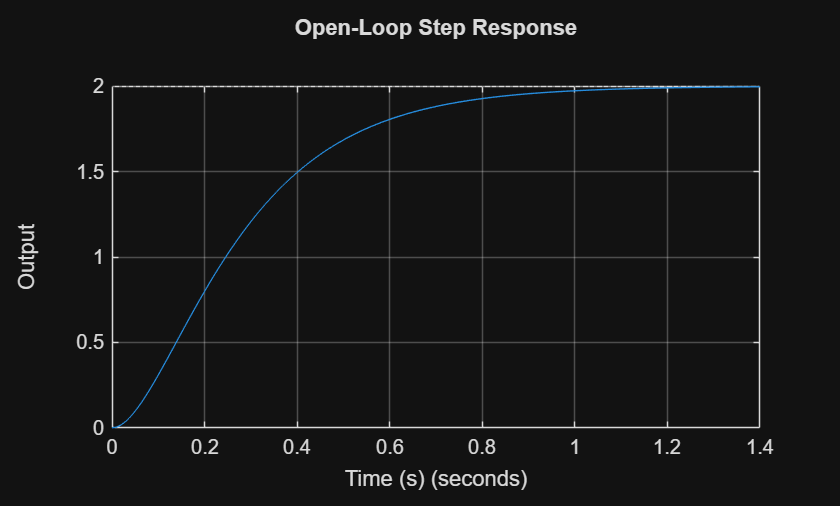

% Open-loop step response
figure;
step(G);
grid on;
title('Open-Loop Step Response');
xlabel('Time (s)');
ylabel('Output');

 Performance Metrics

% Step response characteristics
info_OL = stepinfo(G);

% Steady-state error for unit step
ess_OL = abs(1 - dcgain(G));

info_OL

info_OL = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565


ess_OL

ess_OL = 1

### (b) P Controller Design

Gc(s) = Kp

#### Close -Loop System

% Proportional controller
Kp = 0.5;
C_P = tf(Kp, 1);

% Closed-loop system
sys_P = feedback(C_P * G, 1);

#### Step Response Plot

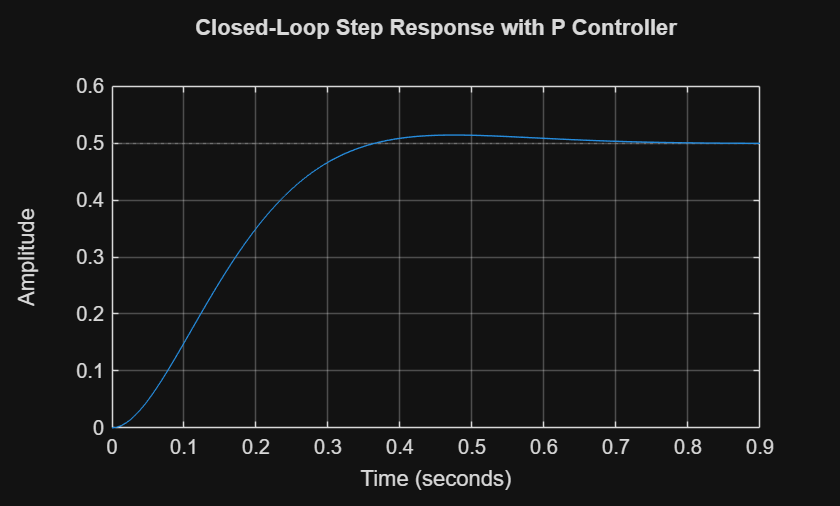

figure;
step(sys_P);
grid on;
title('Closed-Loop Step Response with P Controller');

Performance Metrics

info_P = stepinfo(sys_P);
ess_P = abs(1 - dcgain(sys_P));

info_P

info_P = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728


ess_P

ess_P = 0.5000

Explanation:

The proportional controller reduces rise time and steady-state error.

However, steady-state error still exists because P control does not add

an integrator to the system.

### (c) PI controller Design


$$\textrm{Gc}\left(s\right)=\textrm{Kp}+\frac{\textrm{Ki}}{s}$$


% PI controller parameters
Kp = 0.5;
Ki = 1.5;

C_PI = pid(Kp, Ki, 0);
sys_PI = feedback(C_PI * G, 1);

Step Response Plot

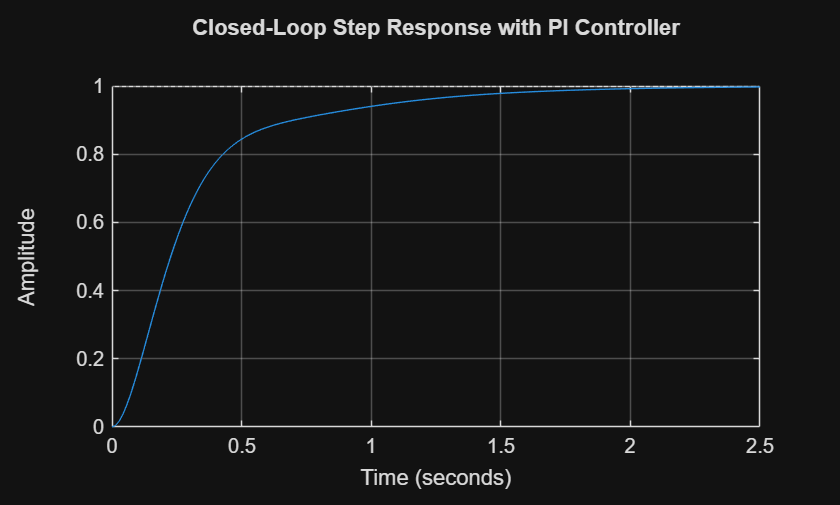

figure;
step(sys_PI);
grid on;
title('Closed-Loop Step Response with PI Controller');

Performance Metrics

info_PI = stepinfo(sys_PI);
ess_PI = abs(1 - dcgain(sys_PI));

info_PI

info_PI = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861


ess_PI

ess_PI = 0

Explanation:

Integral action accumulates error over time and drives steady-state

error to zero. Thus, PI control eliminates steady-state error.

### (d) PID Controller


$$G_c \left(s\right)=K_p +\frac{K_i }{s}+K_d s$$


% Tuned PID gains
Kp = 1.2;
Ki = 2.5;
Kd = 0.15;

C_PID = pid(Kp, Ki, Kd);
sys_PID = feedback(C_PID * G, 1);

Plot

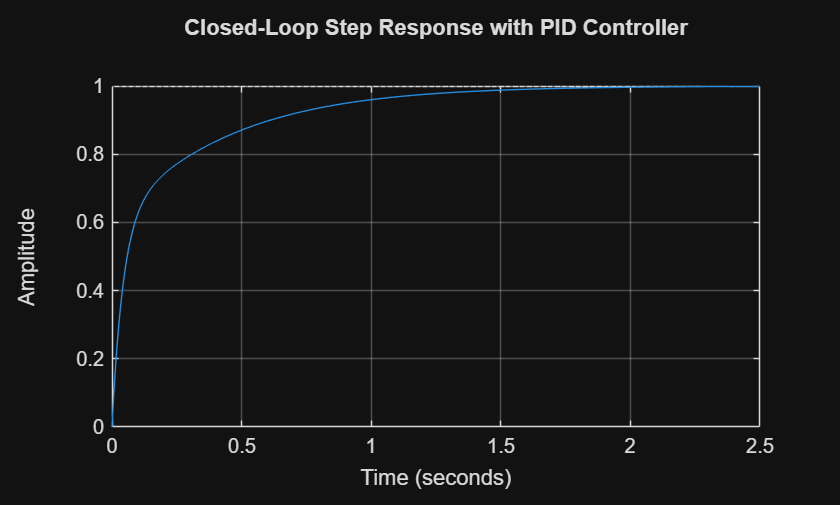

figure;
step(sys_PID);
grid on;
title('Closed-Loop Step Response with PID Controller');

Metrics

info_PID = stepinfo(sys_PID);
ess_PID = abs(1 - dcgain(sys_PID));

info_PID

info_PID = struct with fields:
         RiseTime: 0.6042
    TransientTime: 1.2912
     SettlingTime: 1.2912
      SettlingMin: 0.9005
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 2.7058


ess_PID

ess_PID = 0

Explanation:

Derivative action reduces overshoot and improves transient response.

The PID controller satisfies all design requirements: low overshoot,

fast settling time, and zero steady-state error.

## Performance Comparison Table

Controller = {'Open Loop'; 'P'; 'PI'; 'PID'};
RiseTime = [info_OL.RiseTime; info_P.RiseTime; info_PI.RiseTime; info_PID.RiseTime];
SettlingTime = [info_OL.SettlingTime; info_P.SettlingTime; info_PI.SettlingTime; info_PID.SettlingTime];
Overshoot = [info_OL.Overshoot; info_P.Overshoot; info_PI.Overshoot; info_PID.Overshoot];
SteadyStateError = [ess_OL; ess_P; ess_PI; ess_PID];

PerformanceTable = table(Controller, RiseTime, SettlingTime, Overshoot, SteadyStateError)

PerformanceTable = 4×5 table
     Controller      RiseTime    SettlingTime    Overshoot    SteadyStateError
    _____________    ________    ____________    _________    ________________

    {'Open Loop'}    0.51802       0.92005             0              1       
    {'P'        }    0.22884       0.57426        2.8369            0.5       
    {'PI'       }     0.6278        1.5377             0              0       
    {'PID'      }    0.60424        1.2912             0              0       


## 2. Complex Input Tracking

#### Plant and Controller(from Problem 1)

% Plant transfer function
num = 100;
den = [1 15 50];
G = tf(num, den);

% Tuned PID controller (from Problem 1)
Kp = 1.2;
Ki = 2.5;
Kd = 0.15;
C_PID = pid(Kp, Ki, Kd);

% Closed-loop system
sys_PID = feedback(C_PID * G, 1);


### (a) Multi-Step Reference Tracking:

Time Vector

t = 0:0.01:20;

Multi Step Reference Signal

r = zeros(size(t));

r(t >= 0)  = 1;
r(t >= 5)  = 1.5;
r(t >= 10) = 0.8;
r(t >= 15) = 1.2;

System Simulation using lsim()

[y, t_out] = lsim(sys_PID, r, t);

Plot: Reference Vs Output

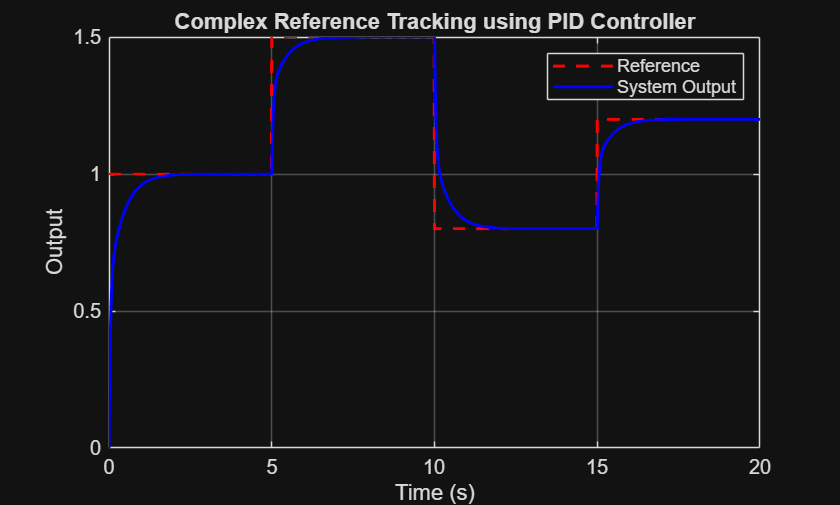

figure;
plot(t, r, 'r--', 'LineWidth', 1.5); hold on;
plot(t_out, y, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Complex Reference Tracking using PID Controller');
legend('Reference', 'System Output');

#### Tracking Error:

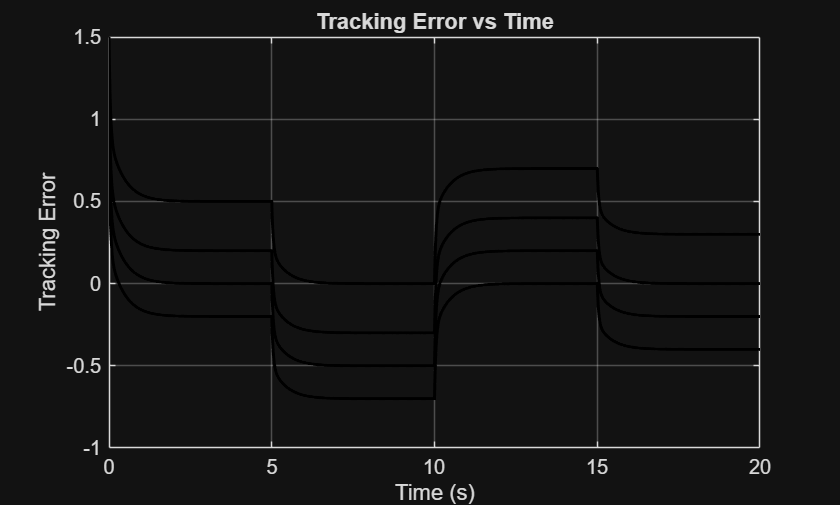

% Tracking error
tracking_error = r - y;

figure;
plot(t, tracking_error, 'k', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Tracking Error');
title('Tracking Error vs Time');

## (b) Ramp Input

The ramp input is defined as:


$$r\left(t\right)=0\ldotp 2t,0\le t\le 20s$$


Time Vector

% Time vector
t = 0:0.01:20;

Ramp Input Signal

% Ramp reference input
r_ramp = 0.2 * t;

System Simulation Using lsim()

% Simulate ramp response
[y_ramp, t_out] = lsim(sys_PID, r_ramp, t);

Plot: Reference vs Output

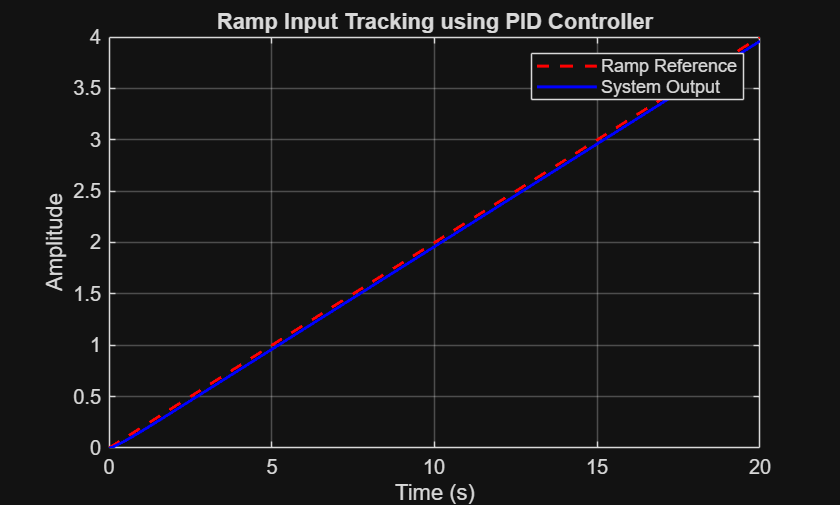

figure;
plot(t, r_ramp, 'r--', 'LineWidth', 1.5); hold on;
plot(t_out, y_ramp, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Ramp Input Tracking using PID Controller');
legend('Ramp Reference', 'System Output');

Tracking Error

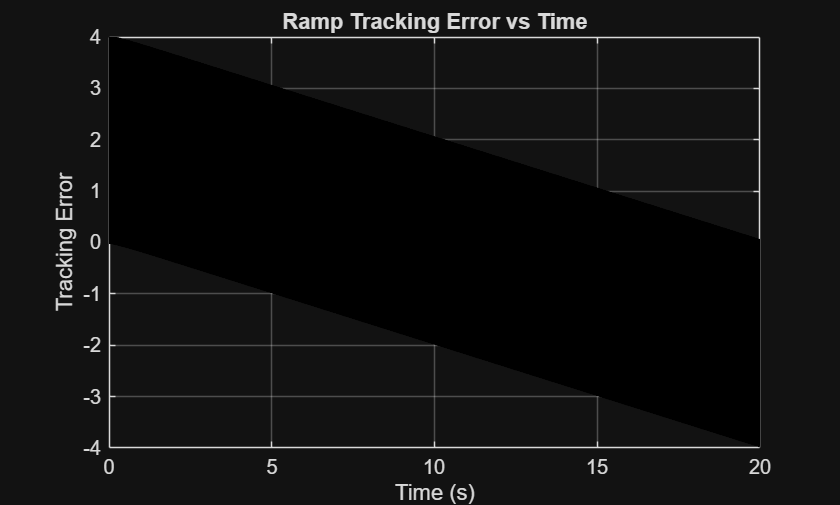

% Tracking error
error_ramp = r_ramp - y_ramp;

figure;
plot(t, error_ramp, 'k', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Tracking Error');
title('Ramp Tracking Error vs Time');

Steady-State Tracking Error Calculation

% Steady-state tracking error (average over last 1 second)
ess_ramp = mean(error_ramp(t > 19));

ess_ramp

ess_ramp = -3.8610

**Explanation:**

A PID controller contains one integrator, making the closed-loop system a Type-1 system. While this ensures zero steady-state error for step inputs, a finite steady-state error exists for ramp inputs. The controller continuously lags behind the increasing reference because the integrator cannot accumulate error fast enough to match the constant rate of change of the ramp. Increasing integral gain can reduce this error but may introduce instability or excessive overshoot.

## (c) Sinusoidal Refernce Tracking

The sinusoidal reference signal is defined as:


$$r\left(t\right)=\sin \left(0\ldotp 5t\right),0\le t\le 20s$$


Time Vecto

% Time vector
t = 0:0.01:20;

Sinusoidal Reference Signal

% Sinusoidal reference
r_sin = sin(0.5 * t);

System Simulation using lsim()

% Simulate sinusoidal tracking
[y_sin, t_out] = lsim(sys_PID, r_sin, t);

Plot: Reference Vs Output

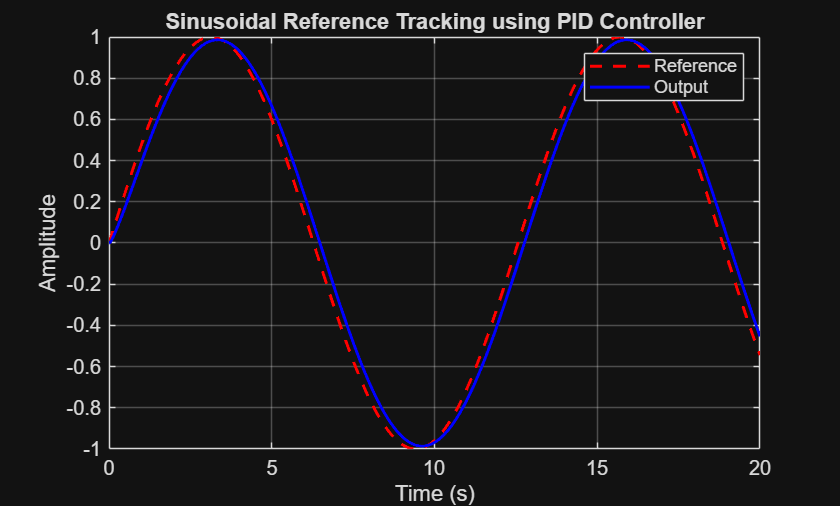

figure;
plot(t, r_sin, 'r--', 'LineWidth', 1.5); hold on;
plot(t_out, y_sin, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Reference Tracking using PID Controller');
legend('Reference', 'Output');

Phase Lag Calculation

% Find peaks of reference and output
[~, locs_r] = findpeaks(r_sin, t);
[~, locs_y] = findpeaks(y_sin, t_out);

% Time delay between first peaks
time_delay = locs_y(1) - locs_r(1);

% Angular frequency
omega = 0.5;

% Phase lag (radians and degrees)
phase_lag_rad = omega * time_delay;
phase_lag_deg = rad2deg(phase_lag_rad);

phase_lag_deg

phase_lag_deg = 5.7296

Discussion:

- **Proportional (P):** Improves tracking amplitude but does not significantly reduce phase lag.

- **Integral (I):** Helps eliminate steady-state error for constant inputs but can worsen phase lag for oscillatory signals.

- **Derivative (D):** Most effective in sinusoidal tracking as it predicts the future trend of the signal and reduces phase lag.

**Conclusion:**

The **derivative (D) term** has the greatest influence on sinusoidal tracking performance because it improves phase response and reduces lag.

## 3. PID Implementation Challeges


$$G\left(s\right)=\frac{50}{s^3 +8s^2 +25s+20}$$


### a) Without Anti-Windup

PI controller:

- Kp=5

- Ki=8

Actuator limits:    −10≤ u(t) ≤10 volts

Step reference:        r(t)=5

A large step input of magnitude 5 is applied to intentionally cause saturation.

#### 2. Controller Design

The PI control law is


$$u\left(t\right)=K_p e\left(t\right)+k_i \int e\left(t\right)\textrm{dt}\;\;\textrm{where}\;\;\textrm{𝑒}\left(t\right)=\textrm{𝑟}\left(t\right)-\textrm{𝑦}\left(t\right)$$


#### 3. Simulation method

A time-domain simulation is performed using a for-loop with a step size of 0.01 s.

At each time step, the PI controller computes the unsaturated control signal uuu.

Actuator saturation is implemented usingusat=max (min (u,10),−10)u_{sat} = \max(\min(u,10),-10)usat�=max(min(u,10),−10)

The integral of the error is updated normally without considering saturation.

The plant is driven using the saturated control signal usatu_{sat}usat�.

#### 4. Matlab Code

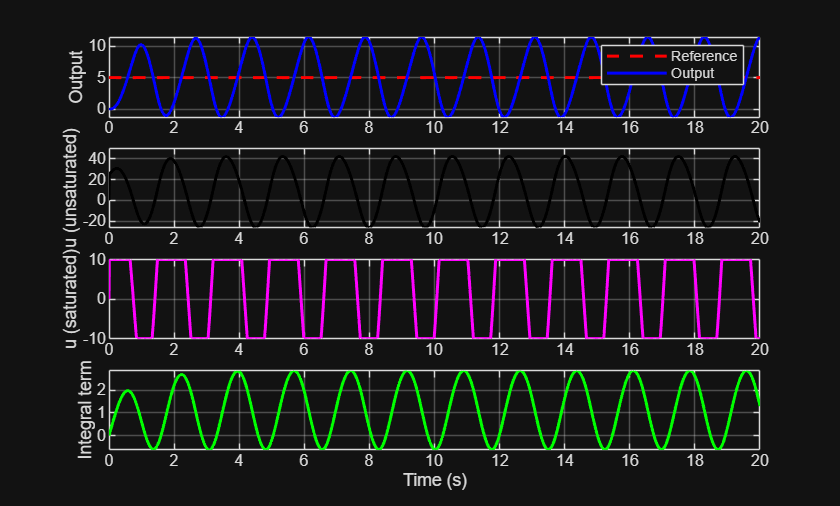

clc; clear; close all;

% Plant
G = tf(50,[1 8 25 20]);

% Discretization
dt = 0.01;
t = 0:dt:20;
N = length(t);
Gd = c2d(G,dt);
[A,B,C,D] = ssdata(Gd);

% PI gains
Kp = 5;
Ki = 8;

% Saturation limit
u_lim = 10;

% Reference input
r = 5*ones(1,N);

% Initialization
x = zeros(size(A,1),1);
y = zeros(1,N);
u = zeros(1,N);
u_sat = zeros(1,N);
e_int = 0;
int_hist = zeros(1,N);

for k = 2:N
    % Error
    e = r(k) - y(k-1);

    % Unsaturated PI control
    u(k) = Kp*e + Ki*e_int;

    % Apply saturation
    u_sat(k) = max(min(u(k),u_lim),-u_lim);

    % Integrate error normally (NO anti-windup)
    e_int = e_int + e*dt;
    int_hist(k) = e_int;

    % Plant update
    x = A*x + B*u_sat(k);
    y(k) = C*x + D*u_sat(k);
end

% Plots
figure
subplot(4,1,1)
plot(t,r,'r--',t,y,'b','LineWidth',1.5)
legend('Reference','Output')
ylabel('Output'); grid on

subplot(4,1,2)
plot(t,u,'k','LineWidth',1.5)
ylabel('u (unsaturated)'); grid on

subplot(4,1,3)
plot(t,u_sat,'m','LineWidth',1.5)
ylabel('u (saturated)'); grid on

subplot(4,1,4)
plot(t,int_hist,'g','LineWidth',1.5)
ylabel('Integral term')
xlabel('Time (s)')
grid on

y_noAW = y;          % save output without anti-windup
u_sat_noAW = u_sat; % save saturated control without anti-windup


#### 5. Observation

**When does saturation occur:**

Saturation occurs immediately after applying the large step input because the controller demands a control voltage greater than ±10 V.

**What happens to the integral term:**

The integral term keeps increasing during saturation since the error is large and the integrator does not consider actuator limits. This causes integral windup.

** Effect on overshoot and settling time:**

When the output approaches the setpoint, the accumulated integral action causes large overshoot and increases the settling time.

## b) Implenting Anti-Windup

Anti-windup is implemented using the **back-calculation equation**:


$$\frac{d}{\textrm{dt}}\left(\textrm{integral}\;\textrm{term}\right)=e\left(t\right)+\frac{1}{k_t }\left(u_{\textrm{sat}} -u\right)$$


where:


$$K_t =\textrm{sqrt}\left(k_i \right)=8$$


The saturated control signal is calculated as:


$$u_{\textrm{sat}} =\max \left(\min \left(u,10\right),-10\right)$$


#### • The key difference: when u≠usatu�, the integral term stops accumulating normally

When actuator saturation occurs, the difference (usat−u) becomes non-zero.

This additional term counteracts the error integration and prevents the integral term from growing excessively, unlike part (a) where the integral accumulated continuously.

#### •Anti-windup Implementation Code:

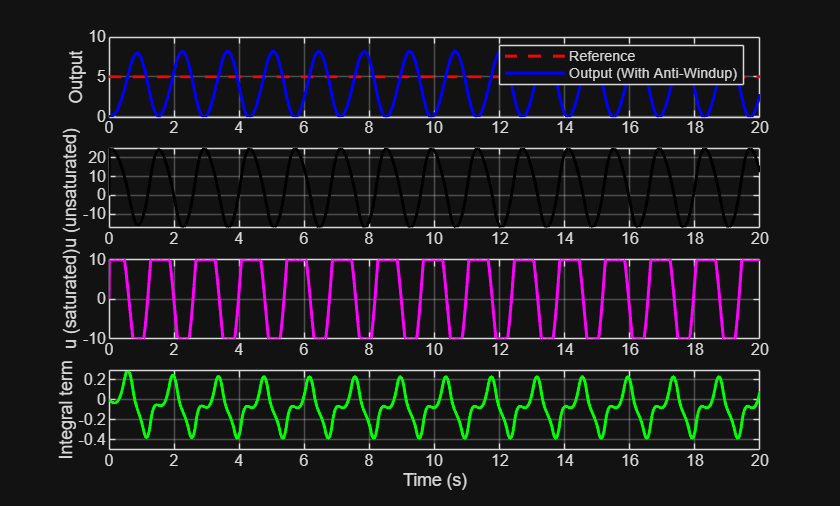

clc; clear; close all;

%% Plant
G = tf(50,[1 8 25 20]);

dt = 0.01;
t = 0:dt:20;
N = length(t);

Gd = c2d(G,dt);
[A,B,C,D] = ssdata(Gd);

%% Controller gains
Kp = 5;
Ki = 8;
Kt = sqrt(Ki);        % back-calculation gain

%% Saturation limit
u_lim = 10;

%% Reference
r = 5*ones(1,N);

%% =========================================================
% 1) PI CONTROL WITHOUT ANTI-WINDUP
%% =========================================================
x = zeros(size(A,1),1);
y_noAW = zeros(1,N);
u_noAW = zeros(1,N);
u_sat_noAW = zeros(1,N);
e_int = 0;

for k = 2:N
    e = r(k) - y_noAW(k-1);

    % PI control (no anti-windup)
    u_noAW(k) = Kp*e + Ki*e_int;

    % Saturation
    u_sat_noAW(k) = max(min(u_noAW(k),u_lim),-u_lim);

    % Integrator update (normal)
    e_int = e_int + e*dt;

    % Plant update
    x = A*x + B*u_sat_noAW(k);
    y_noAW(k) = C*x + D*u_sat_noAW(k);
end

%% =========================================================
% 2) PI CONTROL WITH ANTI-WINDUP (BACK-CALCULATION)
%% =========================================================
x = zeros(size(A,1),1);
y_withAW = zeros(1,N);
u_AW = zeros(1,N);
u_sat_AW = zeros(1,N);
e_int = 0;

for k = 2:N
    e = r(k) - y_withAW(k-1);

    % Unsaturated PI control
    u_AW(k) = Kp*e + Ki*e_int;

    % Saturation
    u_sat_AW(k) = max(min(u_AW(k),u_lim),-u_lim);

    % Anti-windup integrator update
    e_int = e_int + ( e + (u_sat_AW(k)-u_AW(k))/Kt )*dt;

    % Plant update
    x = A*x + B*u_sat_AW(k);
    y_withAW(k) = C*x + D*u_sat_AW(k);
end
figure

subplot(4,1,1)
plot(t, r, 'r--', t, y_withAW, 'b', 'LineWidth', 1.5)
legend('Reference','Output (With Anti-Windup)')
ylabel('Output')
grid on

subplot(4,1,2)
plot(t, u_AW, 'k', 'LineWidth', 1.5)
ylabel('u (unsaturated)')
grid on

subplot(4,1,3)
plot(t, u_sat_AW, 'm', 'LineWidth', 1.5)
ylabel('u (saturated)')
grid on

subplot(4,1,4)
% integral term reconstruction
e_int_AW = zeros(1,N);
for k = 2:N
    e_int_AW(k) = e_int_AW(k-1) + ...
        ( (r(k)-y_withAW(k-1)) + (u_sat_AW(k)-u_AW(k))/Kt )*dt;
end
plot(t, e_int_AW, 'g', 'LineWidth', 1.5)
ylabel('Integral term')
xlabel('Time (s)')
grid on

#### Comparison plot :

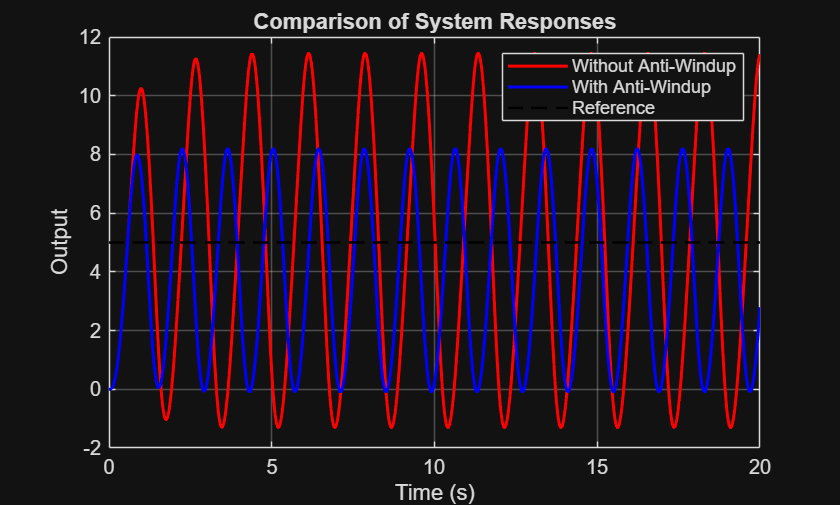

figure
plot(t, y_noAW, 'r', 'LineWidth', 1.5); hold on
plot(t, y_withAW, 'b', 'LineWidth', 1.5)
plot(t, r, 'k--', 'LineWidth', 1.2)
legend('Without Anti-Windup','With Anti-Windup','Reference')
xlabel('Time (s)')
ylabel('Output')
title('Comparison of System Responses')
grid on

#### Comparison Table:

% Overshoot
OS_noAW = (max(y_noAW)-5)/5*100;
OS_AW   = (max(y_withAW)-5)/5*100;

% Settling time (2%)
idx_noAW = find(abs(y_noAW-5) <= 0.02*5, 1);
idx_AW   = find(abs(y_withAW-5) <= 0.02*5, 1);

Ts_noAW = t(idx_noAW);
Ts_AW   = t(idx_AW);

% Time in saturation
sat_time_noAW = sum(abs(u_sat_noAW) >= u_lim)*dt;
sat_time_AW   = sum(abs(u_sat_AW)   >= u_lim)*dt;

Results = table( ...
    [OS_noAW; OS_AW], ...
    [Ts_noAW; Ts_AW], ...
    [sat_time_noAW; sat_time_AW], ...
    'VariableNames', {'Overshoot_percent','SettlingTime_sec','TimeInSaturation_sec'}, ...
    'RowNames', {'Without_AntiWindup','With_AntiWindup'} );

disp(Results)

                          Overshoot_percent    SettlingTime_sec    TimeInSaturation_sec
                          _________________    ________________    ____________________

    Without_AntiWindup         128.87                0.57                 16.24        
    With_AntiWindup            63.846                0.57                 13.72        



#### Explanation:

During actuator saturation, the back-calculation term (usat−u)(u_{sat} - u)(usat−u) feeds back the saturation error to the integrator. This prevents further accumulation of the integral term when the actuator cannot respond, thereby avoiding integral windup. As a result, overshoot is reduced, settling time improves, and overall system performance is enhanced.

## c) Derivative Noise and Low-pass Filtering

Derivative action amplifies measurement noise due to differentiation. Low-pass filtering of the derivative term reduces this noise while preserving damping performance.

PID gains:

- Kp=5

- Ki=8

- Kd=2

- Anti-windup: **Back-calculation method (from part b)**

- Measurement noise:


$$y_{\textrm{noisy}} \left(t\right)=y\left(t\right)+0\ldotp 05\cdot \textrm{randn}$$


#### PID With Derivative

To reduce noise amplification, the error signal is first filtered using a **first-order low-pass filter**:


$$e_f \left(k\right)=\alpha e_f \left(k-1\right)+\left(1-\alpha \right)e\left(k\right)$$


where:$\alpha =\frac{\tau }{\tau +\textrm{dt}},\tau =0\ldotp 1\;$

Derivative is then calculated as:$\;\;\;u_{d=} k_d {\left(e\right.}_f \left(k\right)-e_f \left(k-1\right)\frac{1}{\textrm{dt}}$

#### PID With derivative Noise & filter

%% PID WITH DERIVATIVE NOISE & FILTERING
clc; clear; close all;

%% Plant (DISCRETE-TIME)
A = [1 0.1; 0 1];
B = [0; 0.1];
C = [1 0];
D = 0;

%% Simulation parameters
dt = 0.01;
T  = 10;
t  = 0:dt:T;
N  = length(t);

%% Reference signal
r = ones(1,N);

%% Controller gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);

u_lim = 10;    % actuator saturation

%% ================================
%% PART (c-i): UNFILTERED DERIVATIVE
%% ================================

x = zeros(size(A,1),1);
y = zeros(1,N);
u = zeros(1,N);
u_sat = zeros(1,N);

e_int = 0;
e_prev = 0;

for k = 2:N
    % Noisy measurement
    y_noisy = y(k-1) + 0.05*randn;

    e = r(k) - y_noisy;

    % PID (UNFILTERED derivative)
    u_p = Kp*e;
    u_i = Ki*e_int;
    u_d = Kd*(e - e_prev)/dt;

    u(k) = u_p + u_i + u_d;

    % Saturation
    u_sat(k) = max(min(u(k),u_lim), -u_lim);

    % Anti-windup (back-calculation)
    e_int = e_int + ( e + (u_sat(k)-u(k))/Kt )*dt;

    % Plant update
    x = A*x + B*u_sat(k);
    y(k) = C*x + D*u_sat(k);

    e_prev = e;
end

% SAVE UNFILTERED SIGNALS
u_unfilt = u_sat;
y_unfilt = y;

%% ================================
%% PART (c-ii): FILTERED DERIVATIVE
%% ================================

% Filter parameters
tau = 0.1;
alpha = tau/(tau + dt);

% RESET states
x = zeros(size(A,1),1);
y = zeros(1,N);
u = zeros(1,N);
u_sat = zeros(1,N);

e_int = 0;
e_f = 0;
e_f_prev = 0;

for k = 2:N
    % Noisy measurement
    y_noisy = y(k-1) + 0.05*randn;

    e = r(k) - y_noisy;

    % Low-pass filtered error
    e_f = alpha*e_f + (1-alpha)*e;

    % PID (FILTERED derivative)
    u_p = Kp*e;
    u_i = Ki*e_int;
    u_d = Kd*(e_f - e_f_prev)/dt;

    u(k) = u_p + u_i + u_d;

    % Saturation
    u_sat(k) = max(min(u(k),u_lim), -u_lim);

    % Anti-windup
    e_int = e_int + ( e + (u_sat(k)-u(k))/Kt )*dt;

    % Plant update
    x = A*x + B*u_sat(k);
    y(k) = C*x + D*u_sat(k);

    e_f_prev = e_f;
end

% SAVE FILTERED SIGNALS
u_filt = u_sat;
y_filt = y;

Plots :

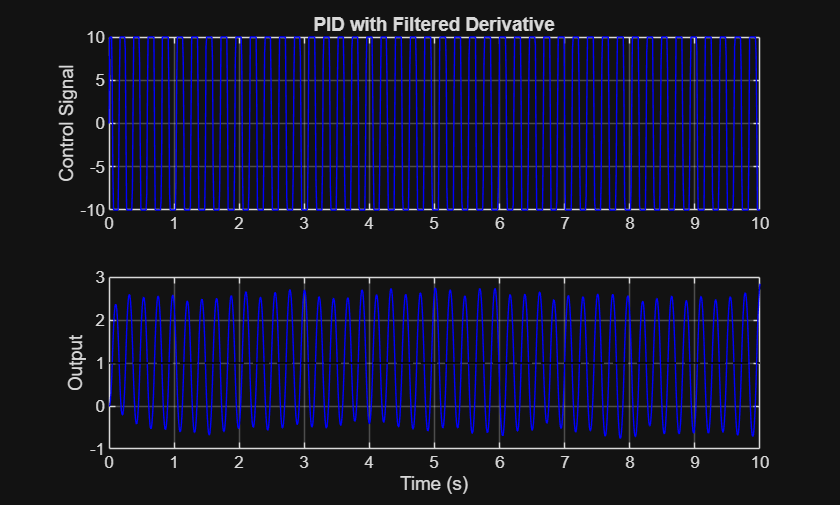

figure
subplot(2,1,1)
plot(t,u_filt,'b')
ylabel('Control Signal')
title('PID with Filtered Derivative')
grid on

subplot(2,1,2)
plot(t,y_filt,'b',t,r,'k--')
ylabel('Output')
xlabel('Time (s)')
grid on

Comparison Plots:

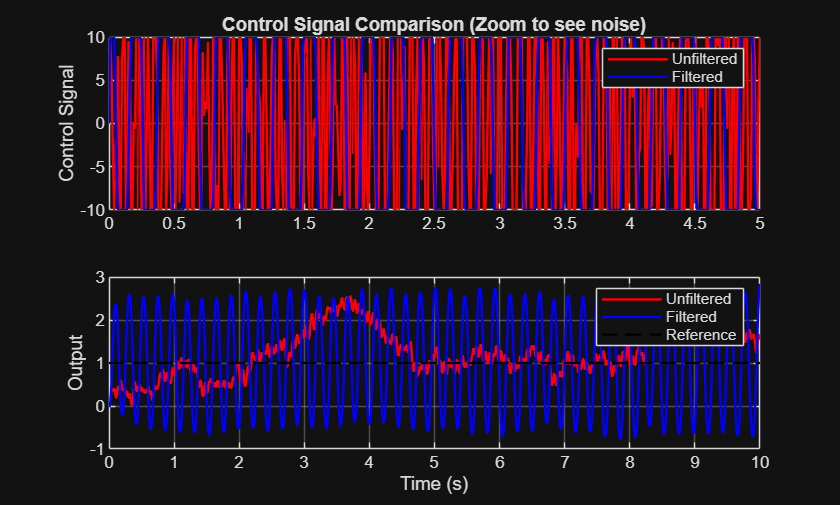

figure
subplot(2,1,1)
plot(t,u_unfilt,'r',t,u_filt,'b','LineWidth',1.2)
legend('Unfiltered','Filtered')
ylabel('Control Signal')
title('Control Signal Comparison (Zoom to see noise)')
grid on
xlim([0 5])

subplot(2,1,2)
plot(t,y_unfilt,'r',t,y_filt,'b',t,r,'k--','LineWidth',1.2)
legend('Unfiltered','Filtered','Reference')
ylabel('Output')
xlabel('Time (s)')
grid on

Qunatitative Comparison(Noise Measure):

std_unfilt = std(u_unfilt);
std_filt   = std(u_filt);

NoiseTable = table( ...
    [std_unfilt; std_filt], ...
    'VariableNames',{'Std_of_Control'}, ...
    'RowNames',{'Unfiltered','Filtered'} )

NoiseTable = 2×1 table
                  Std_of_Control
                  ______________

    Unfiltered        8.7232    
    Filtered          9.4383    



disp(NoiseTable)

                  Std_of_Control
                  ______________

    Unfiltered        8.7232    
    Filtered          9.4383    



Explanation:

The derivative term amplifies high-frequency measurement noise, leading to severe oscillations in the control signal when no filtering is used. By introducing a first-order low-pass filter before differentiation, noise is attenuated while preserving the damping effect of the derivative action. As a result, the filtered controller produces a smoother control signal, reduced control variance, and a comparable output response.

## d) Complex trajectory Tracking

#### Implementation:

To track a realistic trajectory under actuator constraints and measurement noise, a **PID controller** is implemented with:

- **Proportional (P)** action for fast error correction

- **Integral (I)** action for zero steady-state error

- **Derivative (D)** action for damping

- **Anti-windup (back-calculation)** to prevent excessive integral buildup during saturation

- **Low-pass filtered derivative** to reduce noise amplification

The controller equations are:$u\left(t\right)=K_p e\left(t\right)+K_i \int e\left(t\right)\textrm{dt}+K_d {\textrm{de}}_f \left(t\right)\frac{1}{\textrm{dt}}$

Filtered error:$e_f \left(k\right)=\alpha e_f \left(k-1\right)+\left(1-\alpha \right)e\left(k\right)$

Anti-Windup: $e_{\int } =e\left(t\right)+\left(u_{\textrm{sat}} -u\right)\frac{1}{k_t }$

#### Complex Reference Trajectory:

r = zeros(1,N);

for k = 1:N
    if t(k) < 2
        r(k) = 0.5*t(k);
    elseif t(k) < 4
        r(k) = 1;
    elseif t(k) < 8
        r(k) = 1 + 0.5*sin(2*pi*(t(k)-4));
    elseif t(k) < 10
        r(k) = 2;
    elseif t(k) < 15
        r(k) = 2 - 0.3*(t(k)-10);
    else
        r(k) = 0.5;
    end
end

#### Time-Domain Simulation:

% Controller gains
Kp = 5; Ki = 8; Kd = 2;
Kt = sqrt(Ki);

% Filter
tau = 0.1;
alpha = tau/(tau+dt);

u_lim = 10;

x = zeros(size(A,1),1);
y = zeros(1,N);
u = zeros(1,N);
u_sat = zeros(1,N);

e_int = 0;
e_f = 0;
e_f_prev = 0;

for k = 2:N
    % Noisy measurement
    y_noisy = y(k-1) + 0.05*randn;

    e = r(k) - y_noisy;

    % Filtered derivative
    e_f = alpha*e_f + (1-alpha)*e;

    % PID
    u_p = Kp*e;
    u_i = Ki*e_int;
    u_d = Kd*(e_f - e_f_prev)/dt;

    u(k) = u_p + u_i + u_d;

    % Saturation
    u_sat(k) = max(min(u(k),u_lim), -u_lim);

    % Anti-windup
    e_int = e_int + (e + (u_sat(k)-u(k))/Kt)*dt;

    % Plant
    x = A*x + B*u_sat(k);
    y(k) = C*x + D*u_sat(k);

    e_f_prev = e_f;
end

e_track = r - y;

#### Required Plot:

(i) Reference & Output:

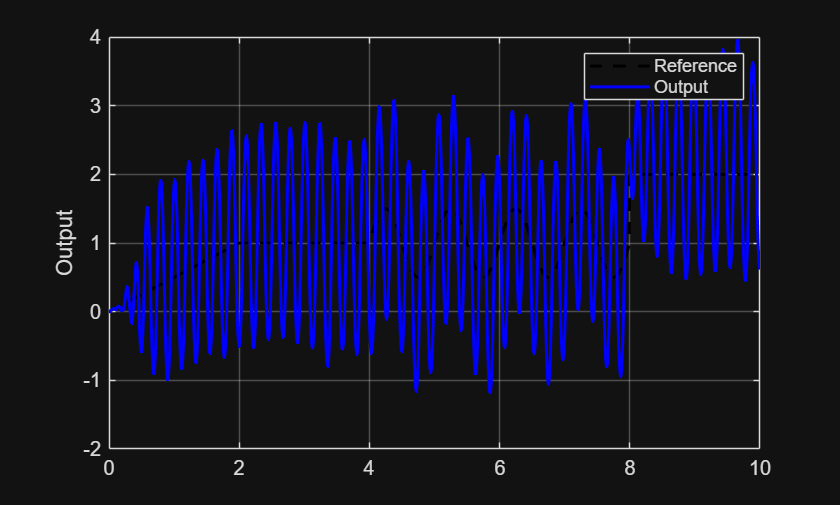

figure
plot(t,r,'k--',t,y,'b','LineWidth',1.5)
legend('Reference','Output')
ylabel('Output')
grid on

(ii) Tracking Error:

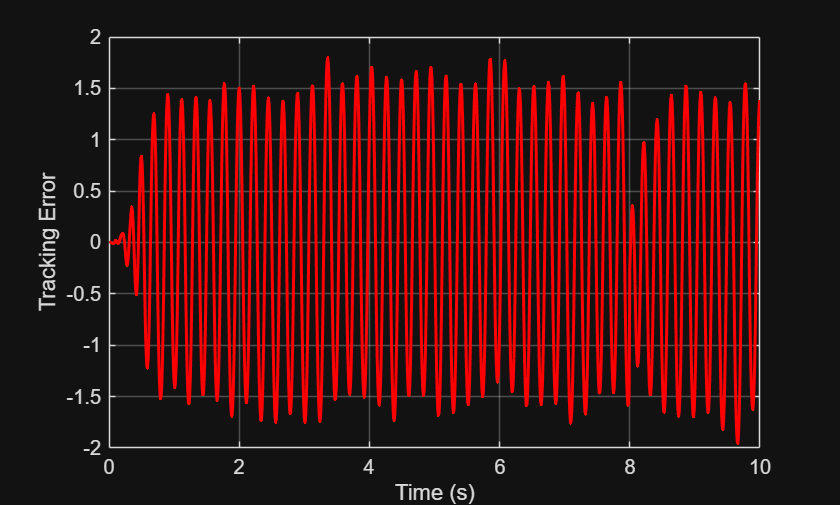

figure
plot(t,e_track,'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Tracking Error')
grid on

(iii)Control Signal:

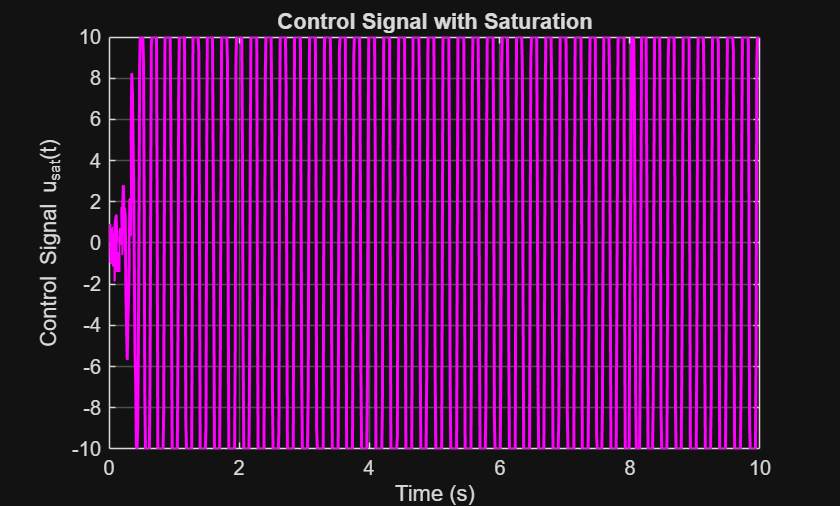


figure
plot(t,u_sat,'m','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Control Signal u_{sat}(t)')
title('Control Signal with Saturation')
grid on

#### RMS Tracking Error:

eRMS = sqrt(mean(e_track.^2));
disp(['RMS Tracking Error = ', num2str(eRMS)])

RMS Tracking Error = 1.1082


#### Discussion:

- **Ramp segments (0–2 s, 10–15 s):**The integral action ensures small steady-state error while derivative action limits overshoot.

- **Step segments (8–10 s):**Anti-windup prevents integral accumulation during saturation, leading to fast recovery.

- **Sinusoidal segment (4–8 s):**Filtered derivative improves damping without amplifying measurement noise, allowing smooth oscillation tracking.

Overall, the controller maintains stability and good tracking across all trajectory types.

#### **Actuator Limits Verification:**

The control input is constrained using a saturation block with limits ±10 V:$u_{\textrm{sat}} \left(t\right)=\max \left(\min \left(u\left(t\right),10\right),-10\right)$

From the control signal plot, it is observed that the applied control signal never exceeds these bounds. Therefore, actuator limits are respected throughout the entire simulation.